d = SessManager.load_special('Mouse2022');

n_bins = 20;
b_a = 10; b_b = 11;

T_shuf = DecodeTensor.shuffle_tensor_common(d.data_tensor, d.tr_dir);
T_shuf = T_shuf(:,:,d.tr_dir==1);

T = d.data_tensor(:,:,d.tr_dir==1);
m = mean(T, 3);
ma = m(:,b_a);
mb = m(:,b_b);

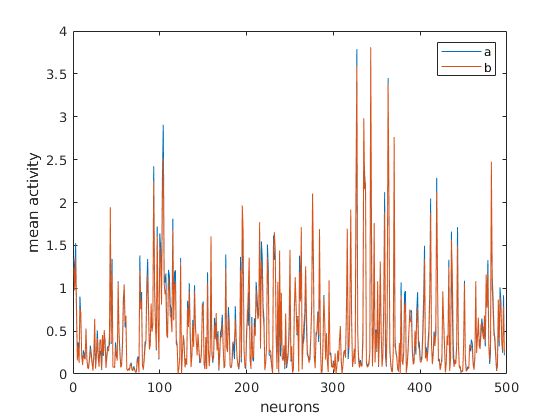

figure;
plot(ma); hold on;
plot(mb);
legend a b
xlabel neurons
ylabel 'mean activity'

%choose_num = 1;

%[~, na] = maxk(ma, choose_num);
%[~, nb] = maxk(mb, choose_num);
%assert(isempty(intersect(na, nb)));
delta_mu = abs(ma - mb);
[~, chosen_neurons] = maxk(delta_mu, 2);
na = chosen_neurons(1);
nb = chosen_neurons(2);

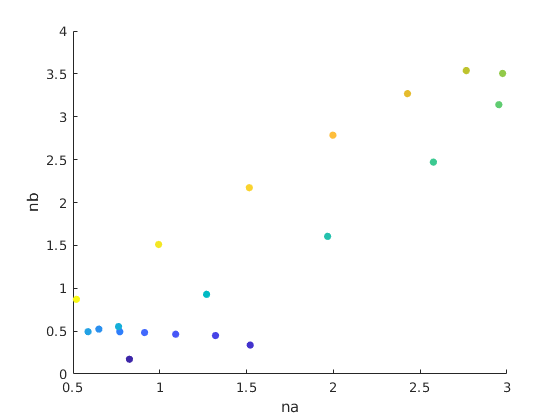

figure;
scatter(mean(m(na,:),1), mean(m(nb,:),1), 30, 1:n_bins, 'filled');
xlabel na
ylabel nb

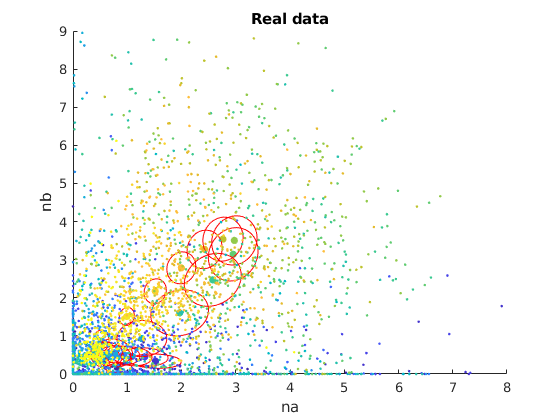

shrink = 0.1;
[x_data, y_data, c_data] = deal(cell(n_bins, 1));
for b_i = 1:n_bins
    x_data{b_i,1} = squeeze(mean(T(na, b_i, :),1));
    y_data{b_i,1} = squeeze(mean(T(nb, b_i, :),1));
    c_data{b_i,1} = y_data{b_i,1}.*0 + b_i;
    hold on;
    X = [x_data{b_i,1}, y_data{b_i,1}];
    bin_angles(b_i) = plot_cov(mean(X), cov(X)*shrink, 'r');
end
hold on;
scatter(cell2mat(x_data), cell2mat(y_data), 4, cell2mat(c_data), 'filled');
title 'Real data'

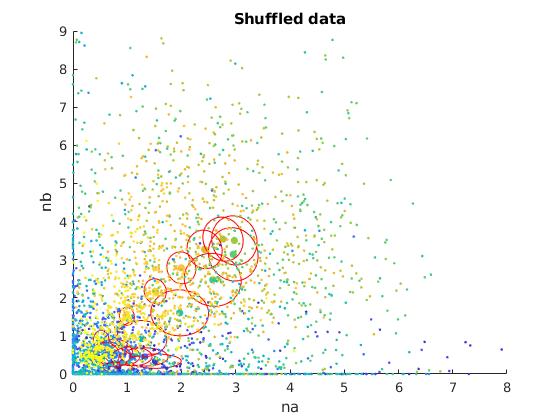

figure;
scatter(mean(m(na,:),1), mean(m(nb,:),1), 30, 1:n_bins, 'filled');
xlabel na
ylabel nb
[x_data, y_data, c_data] = deal(cell(n_bins, 1));
for b_i = 1:n_bins
    x_data{b_i,1} = squeeze(mean(T_shuf(na, b_i, :),1));
    y_data{b_i,1} = squeeze(mean(T_shuf(nb, b_i, :),1));
    c_data{b_i,1} = y_data{b_i,1}.*0 + b_i;
    hold on;
    X = [x_data{b_i,1}, y_data{b_i,1}];
    bin_angles_shuf(b_i) = plot_cov(mean(X), cov(X)*shrink, 'r');
end
hold on;
scatter(cell2mat(x_data), cell2mat(y_data), 4, cell2mat(c_data), 'filled');
title 'Shuffled data'

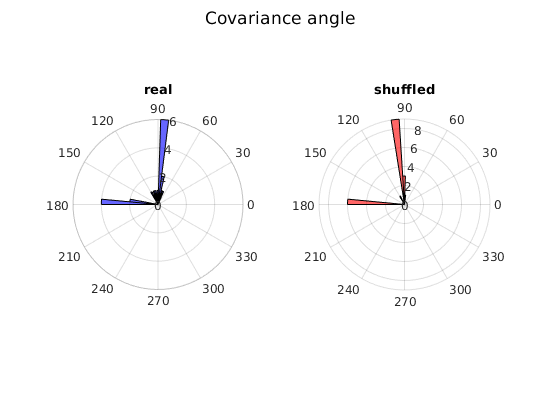

figure;
subplot(1,2,1);
polarhistogram(bin_angles, 25, 'FaceColor', 'b'); %rlim([0 11]);
title real
subplot(1,2,2);
polarhistogram(bin_angles_shuf, 25, 'FaceColor', 'r'); %rlim([0 11]);
title shuffled
sgtitle 'Covariance angle'

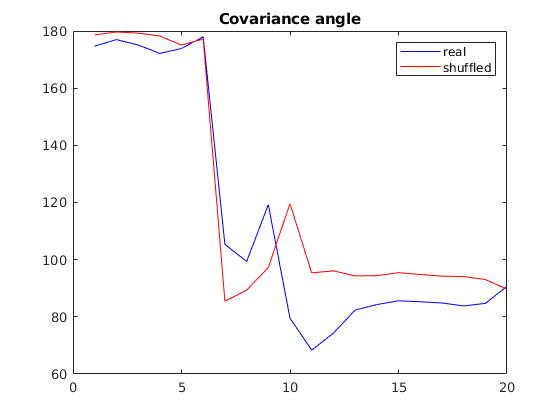

figure;
plot(bin_angles * 180/pi, 'b'); %rlim([0 11]);
hold on;
plot(bin_angles_shuf * 180/pi, 'r'); %rlim([0 11]);
legend real shuffled
title 'Covariance angle'